% filename = ['C:\Users\dell\Desktop\Signal_q\Data\Mental_Math_Trials\OpenBCI_Hard_Mult.txt'];

% filename = ['C:\Users\dell\Desktop\Signal_q\Data\Crystal_Data\Crystal_Prototype\Addition.txt'];

% filename = ['C:\Users\dell\Desktop\Signal_q\Data\Kevin_data2\Prototype_2back'];

% filename = ['C:\Users\dell\Desktop\Signal_q\Data\Kevin_Zhu_Prototype_Eyes_Open'];

% filename = ['C:\Users\dell\Desktop\Signal_q\Data\ScottRamsayData\Prototype_0back.txt']

filename = ['C:\Users\dell\Desktop\Signal_q\Data\001\OpenBCI\Eyes_Closed_1'];

% filename = ['C:\Users\dell\Desktop\Signal_q\Data\Michael\Prototype\ss_2'];

% filename = ['C:\Users\dell\Desktop\Signal_q\Data\003\Prototype\0back_2'];

data = readtable(filename);

% preserve the 8 columns that represent 8 channels
data = data(:, 2:9);

data = table2array(data);
data = data'; 

% import data
low_pass = 1; % Hz
high_pass = 40; % Hz
samprate = 250; % Hz
numchan = 8;
        
matrix_name = 'data';
dataset_name = 'kevin';
sfp = 'C:\Users\dell\Desktop\eeglab2020_0\electrode_positions_8channel.sfp';
EEG.etc.eeglabvers = '2020.0';
EEG = pop_importdata('dataformat','array','nbchan',numchan,'data',matrix_name,'setname',dataset_name,'srate',samprate,'pnts',0,'xmin',0,'chanlocs',sfp);

pop_editset(): channel locations file 'C:\Users\dell\Desktop\eeglab2020_0\electrode_positions_8channel.sfp' found
readlocs(): 'sfp' format assumed from file extension
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (45637) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


        
% bandpass filter
EEG = pop_eegfiltnew(EEG, 'locutoff',low_pass,'hicutoff',high_pass,'plotfreqz',0);

pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 40] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 40.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00



% need: 
% 1. SNR
% 2. Proportion of artifacts
% 3. parietal alpha band power
% 4. frontal theta power

% reject the first and last 30s of the video
[m, n] = size(data); % n is the number of columns
% i.e. n = total number of frames = samprate * length of video in s

start = 30 * samprate; % number of frames to reject
EEG = eeg_eegrej(EEG, [1 start]); % reject first 20s of the video

eeg_insertbound(): 1 boundary (break) events added.
eeg_insertbound(): 1 boundary (break) events added.


        
last = n - start;
EEG = eeg_eegrej(EEG, [last - start, last]); % reject last 20s of the video

eeg_insertbound(): 1 boundary (break) events added.
eeg_insertbound(): 1 boundary (break) events added.


           
% after dataset is imported, preprocessed, and ready to go
length = n - 2 * start % rejected 60s of data

length = 30637


% now, divide the video into 20s intervals 
num_intervals = floor(length / (20 * samprate))

num_intervals = 6


EEG1 = pop_clean_rawdata(EEG, 'FlatlineCriterion','off','ChannelCriterion', 'off','LineNoiseCriterion','off','Highpass','off','BurstCriterion',1,'WindowCriterion',0.1,'BurstRejection','on','Distance','Euclidean','WindowCriterionTolerances',[-inf 7] );

Finding a clean section of the data...
Determining time window rejection thresholds...done.
Keeping 60.6% (74 seconds) of the data.


eeg_insertbound(): 14 boundary (break) events added.
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
eeg_insertbound(): 14 boundary (break) events added.
Estimating calibration statistics; this may take a while...
Determining per-component thresholds...                                            f: +8.838483e+01   |grad|: 4.134664e-14
Gradient norm tolerance reached; options.tolgradnorm = 1e-06.
Total time is 0.112170 [s] (excludes statsfun)
done.
THIS IS RIEMANN ADAPTED PROCESSING!!!
Now cleaning data in 2 blocks                                            f: +2.237092e+05   |grad|: 2.173662e-10
Gradient norm tolerance reached; options.tolgradnorm = 1e-06.
Total time is 0.004547 [s] (excludes statsfun)
.                                            f: +7.375429e+05   |grad|: 9.482107e-10
Gradient norm tolerance reached; options.tolgradnorm = 1e-06.
Total time is 0.004155 [s] (excludes statsfun)
.
Now doing final post-cleanup of the output.
De

eeg_insertbound(): 11 boundary (break) events added.
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
eeg_insertbound(): 11 boundary (break) events added.


Use vis_artifacts to compare the cleaned data to the original.
Done.


EEG2 = pop_clean_rawdata(EEG, 'FlatlineCriterion','off','ChannelCriterion','off','LineNoiseCriterion','off','Highpass','off','BurstCriterion',0.5,'WindowCriterion',0.03,'BurstRejection','off','Distance','Euclidean','WindowCriterionTolerances',[-Inf inf] );

Finding a clean section of the data...
Determining time window rejection thresholds...done.
Keeping 60.6% (74 seconds) of the data.


eeg_insertbound(): 14 boundary (break) events added.
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
eeg_insertbound(): 14 boundary (break) events added.
Estimating calibration statistics; this may take a while...
Determining per-component thresholds...                                            f: +8.838483e+01   |grad|: 4.134664e-14
Gradient norm tolerance reached; options.tolgradnorm = 1e-06.
Total time is 0.004414 [s] (excludes statsfun)
done.
THIS IS RIEMANN ADAPTED PROCESSING!!!
Now cleaning data in 2 blocks                                            f: +2.237092e+05   |grad|: 2.173662e-10
Gradient norm tolerance reached; options.tolgradnorm = 1e-06.
Total time is 0.018057 [s] (excludes statsfun)
.                                            f: +7.375429e+05   |grad|: 9.482107e-10
Gradient norm tolerance reached; options.tolgradnorm = 1e-06.
Total time is 0.000838 [s] (excludes statsfun)
.
Now doing final post-cleanup of the output.
De

Use vis_artifacts to compare the cleaned data to the original.
Done.



% 1. SNR

%{
% ASR that reconstructs artifact
EEG2 = pop_clean_rawdata(EEG, 'FlatlineCriterion','off','ChannelCriterion','off','LineNoiseCriterion','off','Highpass','off','BurstCriterion',5,'WindowCriterion',0.25,'BurstRejection','off','Distance','Euclidean','WindowCriterionTolerances',[-Inf 7] );

% automated artifact removal: ASR that removes artifact, needs to tune parameter
EEG1 = pop_clean_rawdata(EEG, 'FlatlineCriterion','off','ChannelCriterion', 'off','LineNoiseCriterion','off','Highpass','off','BurstCriterion',10,'WindowCriterion',0.25,'BurstRejection','on','Distance','Euclidean','WindowCriterionTolerances',[-inf 7] );

%}

SNRlist = zeros(1, 8);
for i = 1:8 % for all 8 channels
    x = EEG2.data(i, :); % noise reduced signal for channel i
    s = EEG.data(i, :); % original signal for channnel i
    x_sqsum = sum(x.^2);
    s_x_sqsum = sum((s - x).^2);
    
    SNR = 10*log10(x_sqsum/s_x_sqsum);
    
    SNRlist(i) = SNR;
end

avg_SNR = sum(SNRlist)/8; % -ve results mean signal power is lower than noise power


% 2. Proportion of noise
p = (EEG.pnts - EEG1.pnts)/EEG.pnts;

% Prototype
% Stopsignal: 0.2564
% 0back: 0.4230
% eye open: 0.2191
% eye closed: 0.0935
% avg = 0.2480

% OpenBCI
% 0back: 0.3064
% Stopsig: 0.4330
% eye open: 0.3638
% eye closed: 0.1571
% avg = 0.3151

% 3. Parietal Alpha Power: channel 5, 6: eyes closed > eyes open
% demanding power < easy power

PAP_list = [];
for j = 0:num_intervals-1
    sampWin = floor(1 + j * length/num_intervals): floor((j + 1) * length/num_intervals - 1);
    
    %[power_5, freq_5] = spectopo(EEG1.data(5, :), 0, samprate);
    %[power_6, freq_6] = spectopo(EEG1.data(6, :), 0, samprate);
    
    [power_5, freq_5] = spectopo(EEG2.data(5, sampWin), 0, samprate);
    [power_6, freq_6] = spectopo(EEG2.data(6, sampWin), 0, samprate);
    
    alphaPower_5 = mean(10 .^(power_5(freq_5 >= 8 & freq_5 <= 13)/10));
    alphaPower_6 = mean(10 .^(power_6(freq_6 >= 8 & freq_6 <= 13)/10));
    avg_PAP = (alphaPower_5 + alphaPower_6) / 2;
    
    PAP_list(end + 1) = avg_PAP;
end

Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index


Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index


Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index


Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index


Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index


Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index


Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index


Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index


Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index


Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index


Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index


Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index


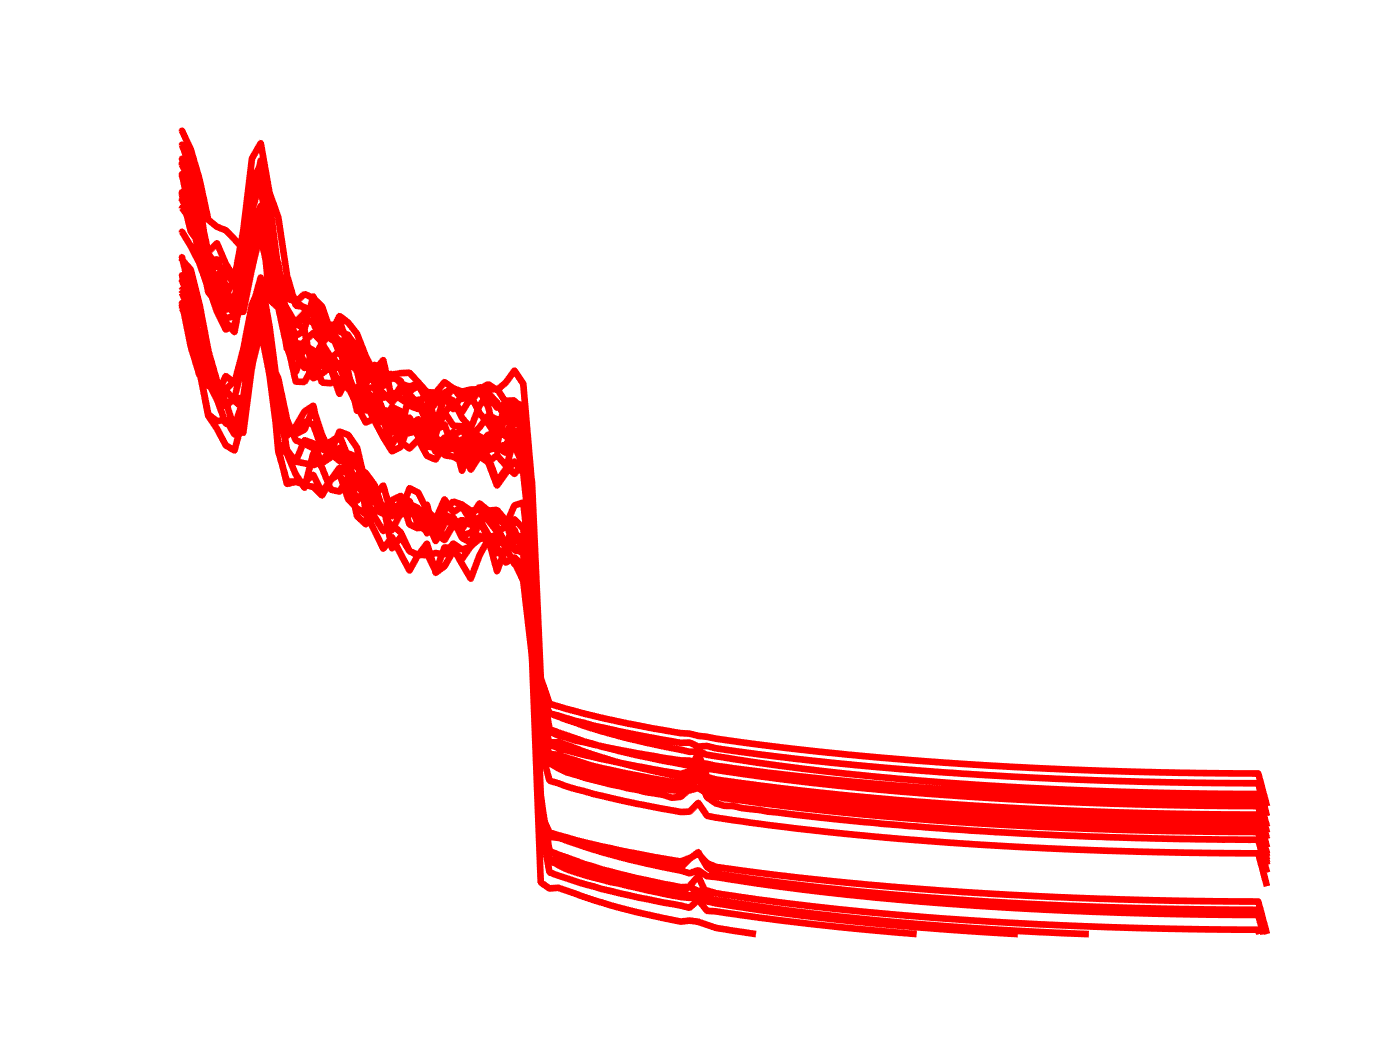

Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index


Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index


Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index


Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index


Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index


Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index


Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index


Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index


Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index


Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index


Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index


Computing spectra (window length 250; fft length: 250; overlap 0):
.


Click on each trace for channel/component index



PAP = mean(PAP_list);

%%% occipital eyes open vs closed channel 7 and 8


% Results for Berger effect alpha block
% OpenBCI: eyes open: avg_PAP = 3.1701, eyes closed: avg_PAP = 5.4979  d = 2.3278
% Prototype: eyes open: avg_PAP = 3.3949, eyes closed: avg_PAP = 4.3826  d = 0.9877


% Results for easy (0 back) vs. demanding (stop signal) tasks
% OpenBCI: easy: avg_PAP = 3.3698, demanding: avg_PAP = 2.4736  d = 0.8962
% Prototype: esay: avg_PAP = 2.0763, demanding: avg_PAP = 1.5838 d = 0.4925

FTP_list = [];

% 4. Frontal Theta Power: Channel 1, 2: demanding power > easy power
for j = 0:num_intervals-1
    %computing log spectrum for different frequencies
    sampWin = floor(1 + j * length/num_intervals): floor((j + 1) * length/num_intervals - 1);
    
    [power_1, freq_1] = spectopo(EEG2.data(1, sampWin), 0, samprate);
    [power_2, freq_2] = spectopo(EEG2.data(2, sampWin), 0, samprate);
    
    thetaPower_1 = mean(10 .^(power_1(freq_1 >= 4 & freq_1 <= 7)/10));
    thetaPower_2 = mean(10 .^(power_2(freq_2 >= 4 & freq_2 <= 7)/10));
    avg_FTP = (thetaPower_1 + thetaPower_2) / 2;
    
    FTP_list(end + 1) = avg_FTP;
       
end


FTP = mean(FTP_list);

% Results for easy (0 back) vs. demanding (stop signal) tasks
% OpenBCI: easy: avg_FTP = 7.7268, demanding: avg_FTP = 3.7952  d = 3.9316 
% Prototype: esay: avg_FTP = 21.5547, demanding: avg_FTP = 14.3259   d = 7.2288



